%task1:
clc; clear; close all;

L = 61;                      
M = (L - 1) / 2;              
omega_c = 0.25 * pi;         
fc = 125;                     
n = 0 : (L - 1);

h = zeros(size(n));
for k = 1:length(n)
    if n(k) == M
       
        h(k) = omega_c / pi;
    else
        h(k) = sin(omega_c*(n(k) - M)) / (pi*(n(k) - M));
    end
end

fs = 1000;              
t = 0 : 1/fs : 1 - 1/fs; 

x1_freq = 50;           
x2_freq = 300;          

x1 = sin(2*pi*x1_freq * t);  
x2 = sin(2*pi*x2_freq * t);  
x  = x1 + x2;          

figure('Name','Original Signals');
subplot(3,1,1);
plot(t, x1, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Signal 1: %d Hz (Cutoff = %d Hz)', x1_freq, fc));
grid on;

subplot(3,1,2);
plot(t, x2, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Signal 2: %d Hz (Cutoff = %d Hz)', x2_freq, fc));
grid on;

subplot(3,1,3);
plot(t, x, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Composite: %d Hz + %d Hz (Cutoff = %d Hz)', x1_freq, x2_freq, fc));
grid on;

y = filter(h, 1, x);

figure('Name','Filtered Signal');
plot(t, y, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Filtered Signal (Cutoff = %d Hz)', fc));
grid on;

N_fft = 2048;
X = fft(x, N_fft);
X_shifted = fftshift(X);

Y = fft(y, N_fft);
Y_shifted = fftshift(Y);

freq_axis = linspace(-fs/2, fs/2, N_fft);

figure('Name','Frequency Domain with fftshift');

subplot(2,1,1);
plot(freq_axis, abs(X_shifted), 'LineWidth', 1.2);
hold on;
xline(-fc, 'r--', 'LineWidth', 1);  
xline(fc,  'r--', 'LineWidth', 1); 
hold off;
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title(sprintf('Original Signal Spectrum (Cutoff = %d Hz)', fc));
grid on;

% Filtered Spectrum
subplot(2,1,2);
plot(freq_axis, abs(Y_shifted), 'LineWidth', 1.2);
hold on;
xline(-fc, 'r--', 'LineWidth', 1);
xline(fc,  'r--', 'LineWidth', 1);
hold off;
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title(sprintf('Filtered Signal Spectrum (Cutoff = %d Hz)', fc));
grid on;

%% 8) Impulse Response Plot (Optional)
figure('Name','Impulse Response');
stem(n, h, 'filled');
xlabel('Sample index (n)');
ylabel('h[n]');
title(sprintf('Lowpass FIR (Rect Window), L=%d, \\omega_c=0.25\\pi, Cutoff=%d Hz', L, fc));
grid on;


%task2:
clc; clear; close all;
n = -20:35;        
omega_c = 0.1 * pi;
h_ideal = zeros(size(n));
for k = 1:length(n)
    if n(k) == 0
        h_ideal(k) = omega_c / pi; 
    else
        h_ideal(k) = sin(omega_c * n(k)) / (pi * n(k));
    end
end

w_rect = ones(size(n));
h_windowed = h_ideal .* w_rect;

figure('Name','Windowing Process');
subplot(3,1,1);
stem(n, h_ideal, 'filled');
xlabel('n'); ylabel('h_{ideal}[n]');
title('Ideal Lowpass Impulse Response');
grid on;

subplot(3,1,2);
stem(n, w_rect, 'filled');
xlabel('n'); ylabel('w[n]');
title('Rectangular Window');
grid on;

subplot(3,1,3);
stem(n, h_windowed, 'filled');
xlabel('n'); ylabel('h[n]');
title('Windowed (Truncated) Impulse Response');
grid on;

N_fft = 1024;           
H = fft(h_windowed, N_fft);
H_shifted = fftshift(H);
freq_axis = linspace(-pi, pi, N_fft);

figure('Name','Frequency Response of Windowed Filter');
plot(freq_axis, abs(H_shifted), 'LineWidth', 1.2);
xlabel('Frequency (rad/sample)');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response of Windowed Ideal Lowpass Filter');
grid on;

fs = 1000;       
t = 0 : 1/fs : 1-1/fs;   
f1 = 30;  
f2 = 250; 

signal1 = sin(2*pi*f1 * t);
signal2 = sin(2*pi*f2 * t);
composite_signal = signal1 + signal2;

filtered_signal = conv(composite_signal, h_windowed, 'same');

figure('Name','Time-Domain Signals');
subplot(2,1,1);
plot(t, composite_signal, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Original Composite Signal (%d Hz + %d Hz)', f1, f2));
grid on;

subplot(2,1,2);
plot(t, filtered_signal, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Filtered Signal (Lowpass)');
grid on;

N_fft_sig = 2048;
Composite_fft = fft(composite_signal, N_fft_sig);
Filtered_fft  = fft(filtered_signal,  N_fft_sig);
Composite_fft_shifted = fftshift(Composite_fft);
Filtered_fft_shifted  = fftshift(Filtered_fft);

freq_axis_sig = linspace(-pi, pi, N_fft_sig);

figure('Name','Frequency-Domain Signals');
subplot(2,1,1);
plot(freq_axis_sig, abs(Composite_fft_shifted), 'LineWidth', 1.2);
xlabel('Frequency (rad/sample)');
ylabel('|X(e^{j\omega})|');
title('Magnitude Spectrum of Original Composite Signal');
grid on;

subplot(2,1,2);
plot(freq_axis_sig, abs(Filtered_fft_shifted), 'LineWidth', 1.2);
xlabel('Frequency (rad/sample)');
ylabel('|X(e^{j\omega})|');
title('Magnitude Spectrum of Filtered Signal');
grid on;


%task3
clc; clear; close all;
omega_p = 0.4 * pi; 
omega_s = 0.5 * pi; 
L = 17;             
N_fft = 8192;       

omega_c = (omega_p + omega_s)/2;  
M = (L - 1)/2;                   
n = 0 : (L - 1);

h_lowpass = zeros(1, L);
for k = 1:length(n)
    if abs(n(k) - M) < eps
        h_lowpass(k) = omega_c / pi;
    else
        h_lowpass(k) = sin(omega_c * (n(k) - M) + eps) / (pi * (n(k) - M) + eps);
    end
end

figure('Name','Lowpass Impulse Response');
stem(n, h_lowpass, 'filled');
xlabel('Sample index n'); ylabel('Amplitude');
title(sprintf('Lowpass Filter (Rect Window), L=%d, \\omega_c=%.2f\\pi', L, omega_c/pi));
grid on;

H_LP = fft(h_lowpass, N_fft);
H_LP_shifted = fftshift(H_LP);

freq_axis_rad = linspace(-pi, pi, N_fft);

figure('Name','Lowpass Frequency Response (Rad/Sample)');
subplot(2,1,1);
plot(freq_axis_rad, abs(H_LP_shifted), 'LineWidth', 1.2);
xlabel('Frequency (rad/sample)');
ylabel('|H_{LP}(e^{j\\omega})|');
title('Magnitude Response (Lowpass)');
grid on;
subplot(2,1,2);
plot(freq_axis_rad, angle(H_LP_shifted), 'LineWidth', 1.2);
xlabel('Frequency (rad/sample)');
ylabel('Phase (radians)');
title('Phase Response (Lowpass)');
grid on;

fs = 1000;        
t = 0 : 1/fs : 1-1/fs;

f_below = 150;     
f_above = 350;    
x_below = sin(2*pi*f_below * t);
x_above = sin(2*pi*f_above * t);
x_composite = x_below + x_above;

y_lowpass = filter(h_lowpass, 1, x_composite);

figure('Name','Lowpass Time-Domain');
subplot(2,1,1);
plot(t, x_composite, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Original Composite (%.0f Hz + %.0f Hz)', f_below, f_above));
grid on;
subplot(2,1,2);
plot(t, y_lowpass, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Filtered Signal (Lowpass)');
grid on;

X = fft(x_composite, N_fft);
Y_LP = fft(y_lowpass, N_fft);
X_shifted = fftshift(X);
Y_LP_shifted = fftshift(Y_LP);

freq_axis_Hz = linspace(-fs/2, fs/2, N_fft);

figure('Name','Lowpass Frequency-Domain (Centered)');
subplot(2,1,1);
plot(freq_axis_Hz, abs(X_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Original Composite Spectrum (Centered)');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, abs(Y_LP_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|Y_{LP}(f)|');
title('Lowpass Filtered Spectrum (Centered)');
grid on;

ap = zeros(1, L);
for k = 1:length(n)
    if abs(n(k) - M) < eps
        ap(k) = 1;  
    else
        ap(k) = sin(pi*(n(k) - M + eps)) / (pi*(n(k) - M + eps));
    end
end

h_highpass = ap - h_lowpass;
figure('Name','LP, AP, HP Impulse Responses');
subplot(3,1,1);
stem(n, h_lowpass, 'b', 'filled');
xlabel('n'); ylabel('Amplitude');
title('Lowpass Filter Impulse Response');
grid on;
subplot(3,1,2);
stem(n, ap, 'r', 'filled');
xlabel('n'); ylabel('Amplitude');
title('All-Pass Function');
grid on;
subplot(3,1,3);
stem(n, h_highpass, 'g', 'filled');
xlabel('n'); ylabel('Amplitude');
title('Highpass Filter (ap - Lowpass)');
grid on;

f_lowHP = 150;   
f_highHP = 350;
x_low = sin(2*pi*f_lowHP * t);
x_high = sin(2*pi*f_highHP * t);
x_compHP = x_low + x_high;

y_highpass = filter(h_highpass, 1, x_compHP);

figure('Name','Highpass Time-Domain');
subplot(2,1,1);
plot(t, x_compHP, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Original Composite (%.0f Hz + %.0f Hz)', f_lowHP, f_highHP));
grid on;
subplot(2,1,2);
plot(t, y_highpass, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Filtered Signal (Highpass)');
grid on;

X_HP = fft(x_compHP, N_fft);
Y_HP = fft(y_highpass, N_fft);
X_HP_shifted = fftshift(X_HP);
Y_HP_shifted = fftshift(Y_HP);

figure('Name','Highpass Frequency-Domain (Centered)');
subplot(2,1,1);
plot(freq_axis_Hz, abs(X_HP_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|X_{HP}(f)|');
title('Original Composite Spectrum (Centered)');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, abs(Y_HP_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|Y_{HP}(f)|');
title('Highpass Filtered Spectrum (Centered)');
grid on;


%task 4:
function h_hp = LVHPFViaSincLPFRectwin(wc, L)

M = (L - 1) / 2;
n = 0:(L-1);

h_lp = zeros(1, L);
for k = 1:length(n)
    if n(k) == M
        h_lp(k) = wc / pi;
    else
        h_lp(k) = sin(wc * (n(k) - M)) / (pi * (n(k) - M));
    end
end

ap = zeros(1, L);
for k = 1:length(n)
    if n(k) == M
        ap(k) = 1;
    else
        ap(k) = sin(pi * (n(k) - M)) / (pi * (n(k) - M));
    end
end

h_hp = ap - h_lp;

end

clc; clear; close all;
%making high pass filter below
wc = 0.3 * pi;  
L = 51;          
fs = 1000;     

h_hp = LVHPFViaSincLPFRectwin(wc, L);

n = 0:(L-1);
figure('Name','High-Pass Filter Impulse Response');
stem(n, h_hp, 'filled');
xlabel('Sample index n');
ylabel('Amplitude');
title(sprintf('High-Pass Filter Impulse Response, wc = %.2f\\pi, L = %d', wc/pi, L));
grid on;

N_fft = 2048;
H_hp = fft(h_hp, N_fft);
H_hp_shifted = fftshift(H_hp);
freq_axis = linspace(-fs/2, fs/2, N_fft);

figure('Name','High-Pass Frequency Response');
subplot(2,1,1);
plot(freq_axis, abs(H_hp_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response of High-Pass Filter');
grid on;
subplot(2,1,2);
plot(freq_axis, angle(H_hp_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Response of High-Pass Filter');
grid on;

f_c = (wc/(2*pi)) * fs; 
fprintf('High-pass filter cutoff frequency: %.2f Hz\n', f_c);

t = 0:1/fs:1-1/fs;

x_low = sin(2*pi*100*t);
x_high = sin(2*pi*300*t);
x_composite = x_low + x_high;

y_hp = filter(h_hp, 1, x_composite);

figure('Name','High-Pass Time-Domain Comparison');
subplot(2,1,1);
plot(t, x_composite, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Composite Signal (100 Hz + 300 Hz)');
grid on;
subplot(2,1,2);
plot(t, y_hp, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (High-Pass)');
grid on;

X_orig = fft(x_composite, N_fft);
Y_filtered = fft(y_hp, N_fft);
X_orig_shifted = fftshift(X_orig);
Y_filtered_shifted = fftshift(Y_filtered);

figure('Name','High-Pass Frequency-Domain Comparison');
subplot(2,1,1);
plot(freq_axis, abs(X_orig_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Spectrum of Original Composite Signal');
grid on;
subplot(2,1,2);
plot(freq_axis, abs(Y_filtered_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Spectrum of High-Pass Filtered Signal');
grid on;

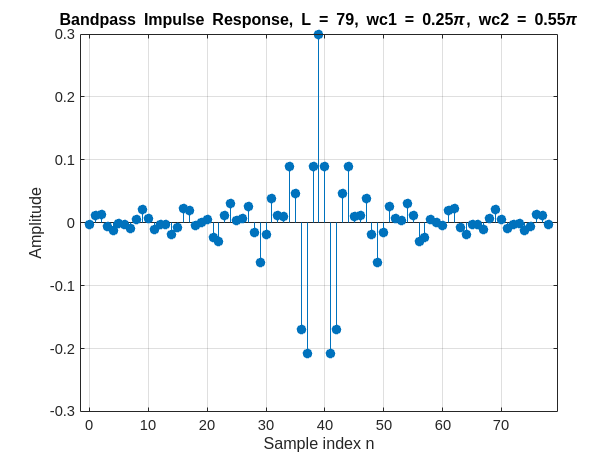

%task5
function h_bp = LVBPFViaSincLPFRectwin(wc1, wc2, L)

M = (L - 1) / 2;
n = 0:(L - 1);
h_bp = zeros(1, L);

for k = 1:length(n)
    if abs(n(k) - M) < eps
        h_bp(k) = (wc2 - wc1) / pi;
    else
        h_bp(k) = ( sin(wc2*(n(k)-M)) - sin(wc1*(n(k)-M)) ) / (pi*(n(k)-M));
    end
end

end

clc; clear; close all;

L_bp = 79;                    
wc1 = 0.25 * pi;              
wc2 = 0.55 * pi;               
fs = 1000;                     
N_fft = 8192;                 
M_bp = (L_bp - 1)/2; 
n_bp = 0:(L_bp-1);
h_bp = zeros(1, L_bp);
for k = 1:length(n_bp)
    if abs(n_bp(k) - M_bp) < eps
        h_bp(k) = (wc2 - wc1)/pi;
    else
        h_bp(k) = ( sin(wc2*(n_bp(k)-M_bp)) - sin(wc1*(n_bp(k)-M_bp)) ) / (pi*(n_bp(k)-M_bp));
    end
end

figure('Name','Task 5 - Bandpass Filter Impulse Response');
stem(n_bp, h_bp, 'filled');
xlabel('Sample index n'); ylabel('Amplitude');
title(sprintf('Bandpass Impulse Response, L = %d, wc1 = %.2f\\pi, wc2 = %.2f\\pi', L_bp, wc1/pi, wc2/pi));
grid on;

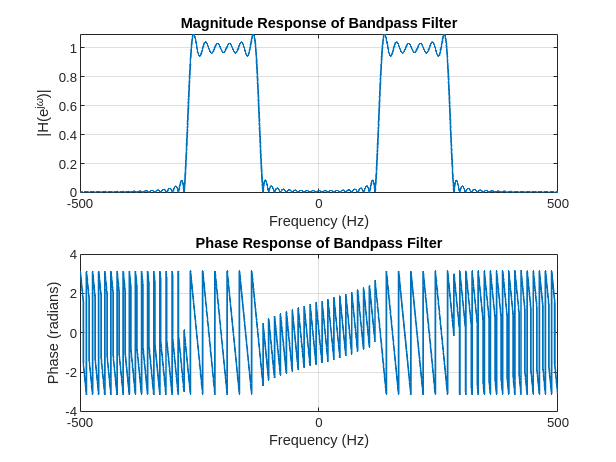


H_bp = fft(h_bp, N_fft);
H_bp_shifted = fftshift(H_bp);
freq_axis_Hz = linspace(-fs/2, fs/2, N_fft);

figure('Name','Task 5 - Bandpass Frequency Response');
subplot(2,1,1);
plot(freq_axis_Hz, abs(H_bp_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response of Bandpass Filter');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, angle(H_bp_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Response of Bandpass Filter');
grid on;

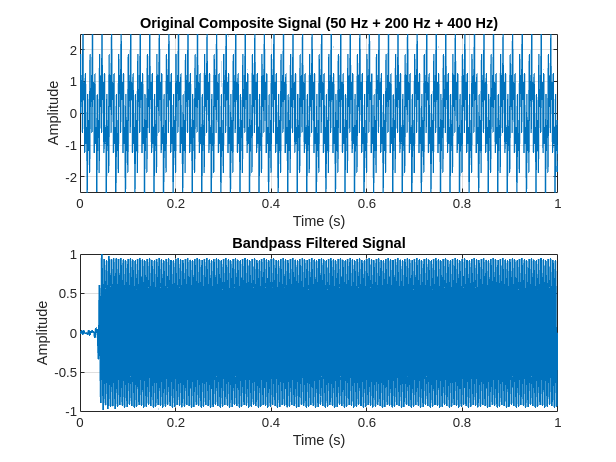


t = 0:1/fs:1-1/fs;  
x1 = sin(2*pi*50*t);   
x2 = sin(2*pi*200*t);  
x3 = sin(2*pi*400*t);  
x_comp_bp = x1 + x2 + x3;

y_bp = filter(h_bp, 1, x_comp_bp);

figure('Name','Task 5 - Time Domain Comparison (Bandpass)');
subplot(2,1,1);
plot(t, x_comp_bp, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Original Composite Signal (50 Hz + 200 Hz + 400 Hz)');
grid on;
subplot(2,1,2);
plot(t, y_bp, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Bandpass Filtered Signal');
grid on;

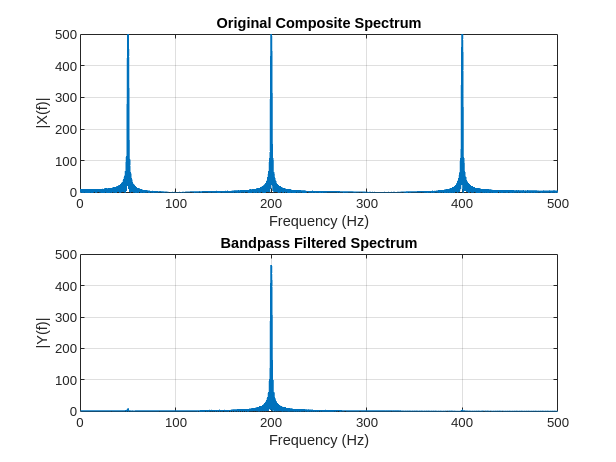


X_bp = fft(x_comp_bp, N_fft);
Y_bp_out = fft(y_bp, N_fft);
f_axis_onesided = linspace(0, fs/2, N_fft/2+1);
X_bp_onesided = abs(X_bp(1:N_fft/2+1));
Y_bp_onesided = abs(Y_bp_out(1:N_fft/2+1));

figure('Name','Task 5 - Frequency Domain (One-Sided, Bandpass)');
subplot(2,1,1);
plot(f_axis_onesided, X_bp_onesided, 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title('Original Composite Spectrum');
grid on;
subplot(2,1,2);
plot(f_axis_onesided, Y_bp_onesided, 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|Y(f)|');
title('Bandpass Filtered Spectrum');
grid on;


fprintf('For fs = %d Hz: wc1 = 0.25*pi corresponds to approx. %.1f Hz, wc2 = 0.55*pi corresponds to approx. %.1f Hz.\n', fs, (0.25/2)*fs, (0.55/2)*fs);

For fs = 1000 Hz: wc1 = 0.25*pi corresponds to approx. 125.0 Hz, wc2 = 0.55*pi corresponds to approx. 275.0 Hz.


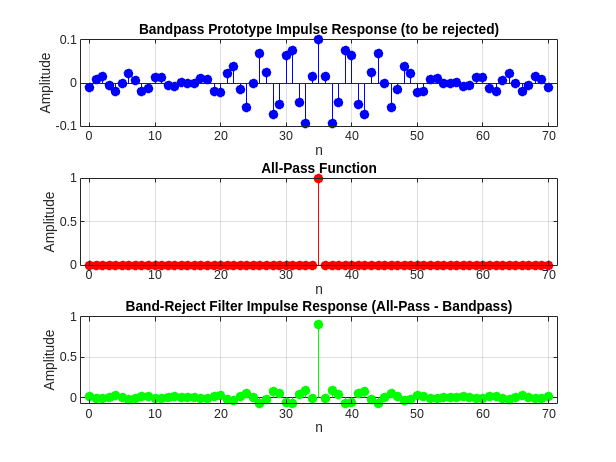

%band reject
L_br = 71;
M_br = (L_br - 1)/2;
wc1_br = 0.4 * pi;
wc2_br = 0.5 * pi; 
n_br = 0:(L_br-1);
h_bp_br = zeros(1, L_br);
for k = 1:length(n_br)
    if abs(n_br(k) - M_br) < eps
        h_bp_br(k) = (wc2_br - wc1_br)/pi;
    else
        h_bp_br(k) = ( sin(wc2_br*(n_br(k)-M_br)) - sin(wc1_br*(n_br(k)-M_br)) ) / (pi*(n_br(k)-M_br));
    end
end

h_allpass = zeros(1, L_br);
for k = 1:length(n_br)
    if abs(n_br(k) - M_br) < eps
        h_allpass(k) = 1;
    else
        h_allpass(k) = sin(pi*(n_br(k)-M_br)) / (pi*(n_br(k)-M_br));
    end
end

h_br = h_allpass - h_bp_br;

figure('Name','Task 12 - Band-Reject Filter Impulse Responses');
subplot(3,1,1);
stem(n_br, h_bp_br, 'b','filled');
xlabel('n'); ylabel('Amplitude');
title('Bandpass Prototype Impulse Response (to be rejected)');
grid on;
subplot(3,1,2);
stem(n_br, h_allpass, 'r','filled');
xlabel('n'); ylabel('Amplitude');
title('All-Pass Function');
grid on;
subplot(3,1,3);
stem(n_br, h_br, 'g','filled');
xlabel('n'); ylabel('Amplitude');
title('Band-Reject Filter Impulse Response (All-Pass - Bandpass)');
grid on;

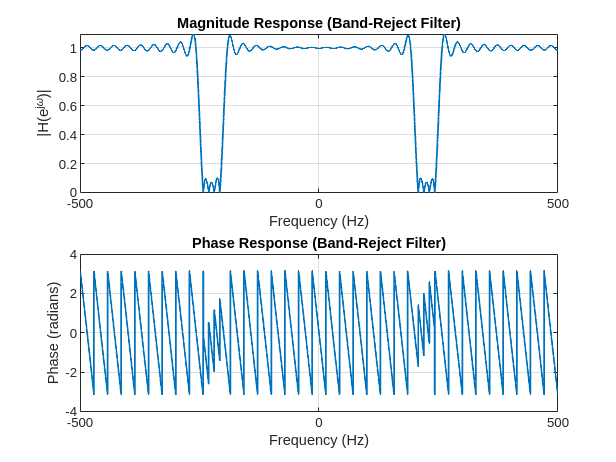


H_br = fft(h_br, N_fft);
H_br_shifted = fftshift(H_br);
figure('Name','Task 12 - Band-Reject Frequency Response');
subplot(2,1,1);
plot(freq_axis_Hz, abs(H_br_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|H(e^{j\omega})|');
title('Magnitude Response (Band-Reject Filter)');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, angle(H_br_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('Phase (radians)');
title('Phase Response (Band-Reject Filter)');
grid on;

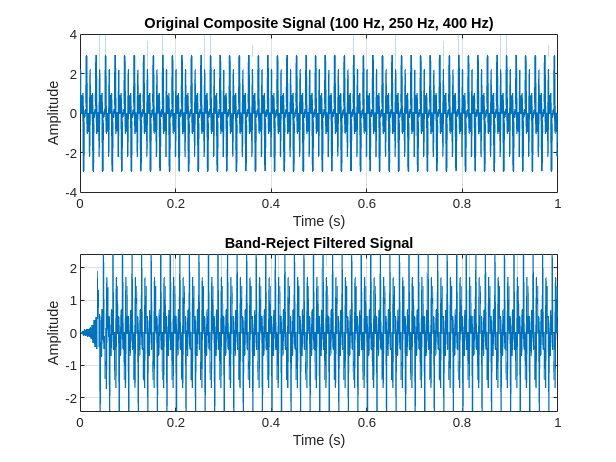


x1_br = sin(2*pi*100*t); 
x2_br = sin(2*pi*250*t);  
x3_br = sin(2*pi*400*t); 
x_comp_br = x1_br + x2_br + x3_br;
y_br = filter(h_br, 1, x_comp_br);

figure('Name','Task 12 - Band-Reject Time Domain');
subplot(2,1,1);
plot(t, x_comp_br, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Original Composite Signal (100 Hz, 250 Hz, 400 Hz)');
grid on;
subplot(2,1,2);
plot(t, y_br, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Band-Reject Filtered Signal');
grid on;

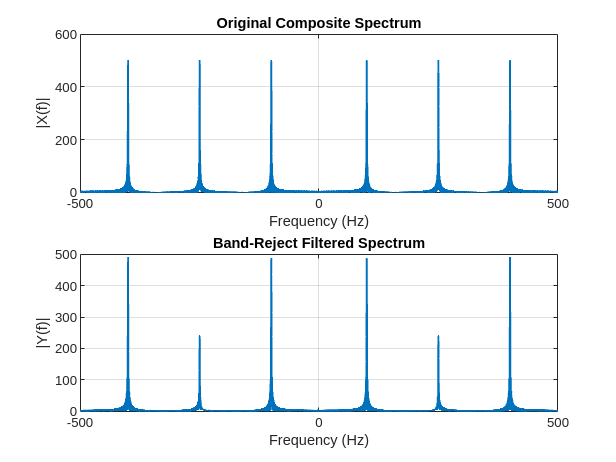


X_br = fft(x_comp_br, N_fft);
Y_br_out = fft(y_br, N_fft);
X_br_shifted = fftshift(X_br);
Y_br_shifted = fftshift(Y_br_out);
figure('Name','Task 12 - Band-Reject Frequency Domain');
subplot(2,1,1);
plot(freq_axis_Hz, abs(X_br_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title('Original Composite Spectrum');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, abs(Y_br_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|Y(f)|');
title('Band-Reject Filtered Spectrum');
grid on;

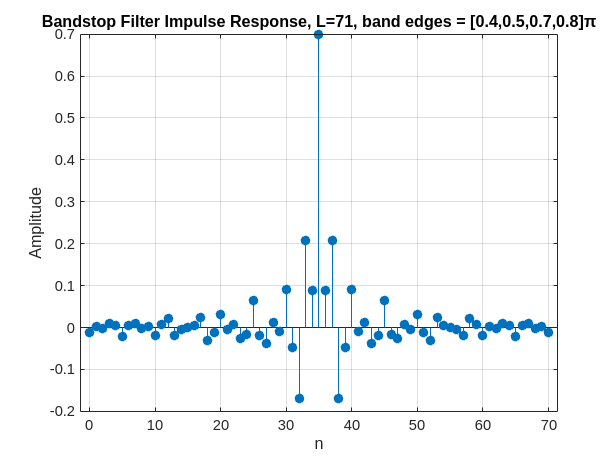


%bandstop:
L_bs = 71;
M_bs = (L_bs - 1)/2;
n_bs = 0:(L_bs-1);

wc1_bs = 0.45 * pi;
wc2_bs = 0.75 * pi;

h_bp_bs = zeros(1, L_bs);
for k = 1:length(n_bs)
    if abs(n_bs(k) - M_bs) < eps
        h_bp_bs(k) = (wc2_bs - wc1_bs)/pi;
    else
        h_bp_bs(k) = ( sin(wc2_bs*(n_bs(k)-M_bs)) - sin(wc1_bs*(n_bs(k)-M_bs)) ) / (pi*(n_bs(k)-M_bs));
    end
end

h_allpass_bs = zeros(1, L_bs);
for k = 1:length(n_bs)
    if abs(n_bs(k) - M_bs) < eps
        h_allpass_bs(k) = 1;
    else
        h_allpass_bs(k) = sin(pi*(n_bs(k)-M_bs)) / (pi*(n_bs(k)-M_bs));
    end
end

h_bs = h_allpass_bs - h_bp_bs;

figure('Name','Task 13 - Bandstop Filter Impulse Response');
stem(n_bs, h_bs, 'filled');
xlabel('n'); ylabel('Amplitude');
title(sprintf('Bandstop Filter Impulse Response, L=%d, band edges = [0.4,0.5,0.7,0.8]π', L_bs));
grid on;

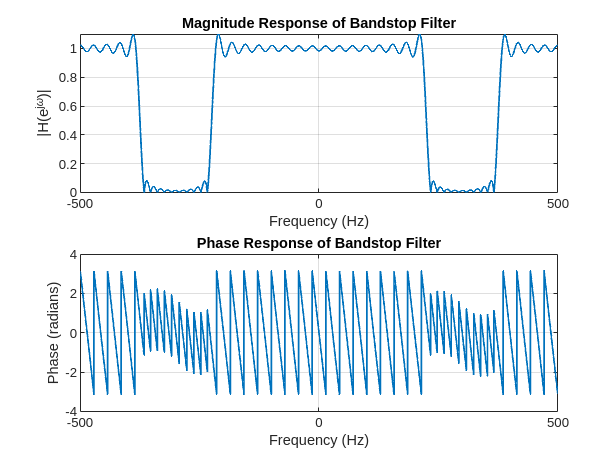


H_bs = fft(h_bs, N_fft);
H_bs_shifted = fftshift(H_bs);
figure('Name','Task 13 - Bandstop Frequency Response');
subplot(2,1,1);
plot(freq_axis_Hz, abs(H_bs_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|H(e^{j\omega})|');
title('Magnitude Response of Bandstop Filter');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, angle(H_bs_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('Phase (radians)');
title('Phase Response of Bandstop Filter');
grid on;

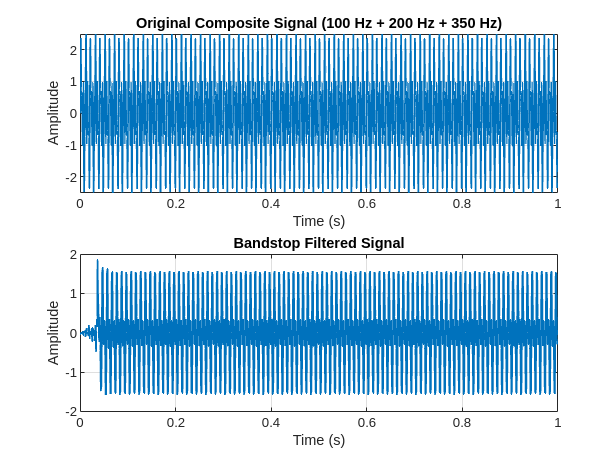


x1_bs = sin(2*pi*100*t);  
x2_bs = sin(2*pi*200*t);   
x3_bs = sin(2*pi*350*t);   
x_comp_bs = x1_bs + x2_bs + x3_bs;
y_bs = filter(h_bs, 1, x_comp_bs);

figure('Name','Task 13 - Bandstop Time Domain Comparison');
subplot(2,1,1);
plot(t, x_comp_bs, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Original Composite Signal (100 Hz + 200 Hz + 350 Hz)');
grid on;
subplot(2,1,2);
plot(t, y_bs, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Bandstop Filtered Signal');
grid on;

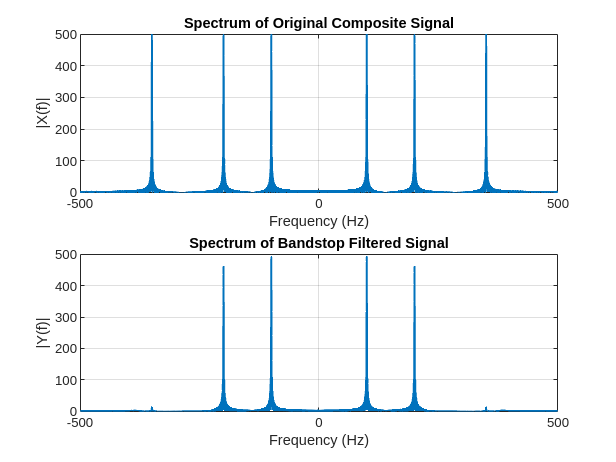


X_bs = fft(x_comp_bs, N_fft);
Y_bs_out = fft(y_bs, N_fft);
X_bs_shifted = fftshift(X_bs);
Y_bs_shifted = fftshift(Y_bs_out);
figure('Name','Task 13 - Bandstop Frequency Domain Comparison');
subplot(2,1,1);
plot(freq_axis_Hz, abs(X_bs_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title('Spectrum of Original Composite Signal');
grid on;
subplot(2,1,2);
plot(freq_axis_Hz, abs(Y_bs_shifted), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|Y(f)|');
title('Spectrum of Bandstop Filtered Signal');
grid on;